# 2-1

## 2-1-a

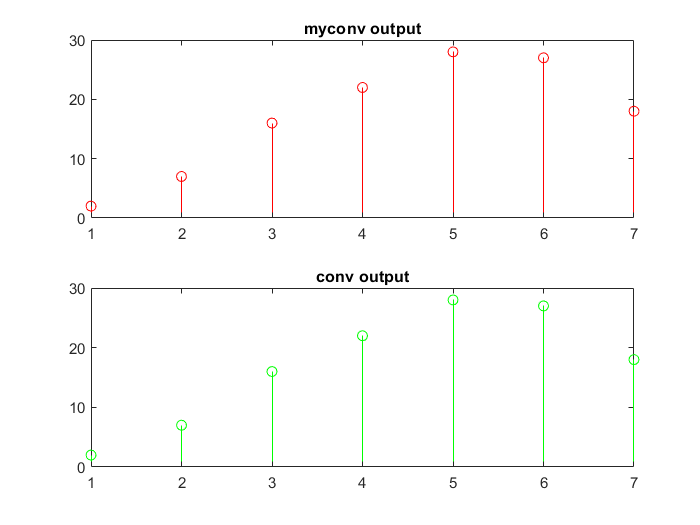

clc;
clear all;

x=[1,2,3];
h=[2 3 4 5 6 ];
figure(1);
subplot(2,1,1);
stem(myconv(x,h),'r');
title('myconv output')

subplot(2,1,2);
stem(conv(x,h),'g');
title('conv output');

### As we see the myconv and MATLAB 's local function Conv are equivalent

## 2-1-b

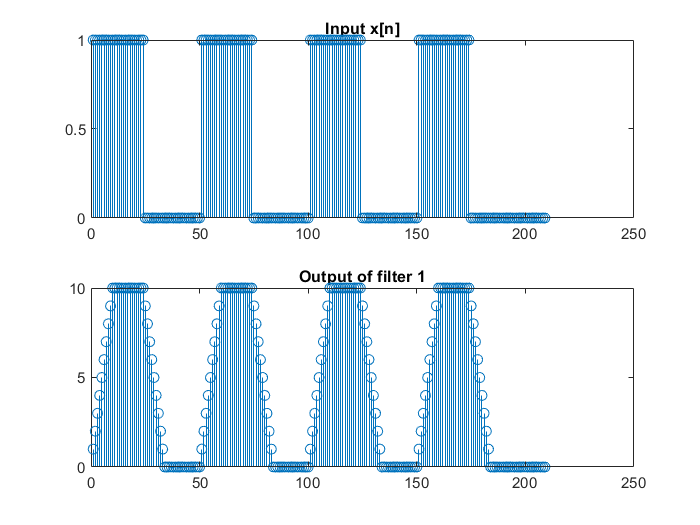

% Creating the desired square wave

x_n=[];
x_n(1:25)=1;
x_n(25:50)=0;
x_n=[x_n x_n x_n x_n zeros(1,9)];



% Defining h[n]
%----------------------------------------------
x_n_shifts={};
x_n_shifts{1}=x_n;

for i=1:9
    x_n_shifts{i+1}=[zeros(1,i) x_n(1:(209-i))];
    
end


total=zeros(1,length(x_n_shifts{i}));
for i=1:10
    total= total + x_n_shifts{i};
end

y1_n=total;
%------------------------------------------------

figure(2);
subplot(2,1,1);
stem(x_n);
title('Input x[n]');

subplot(2,1,2);
stem(y1_n);
title('Output of filter 1');

## 2-1-c

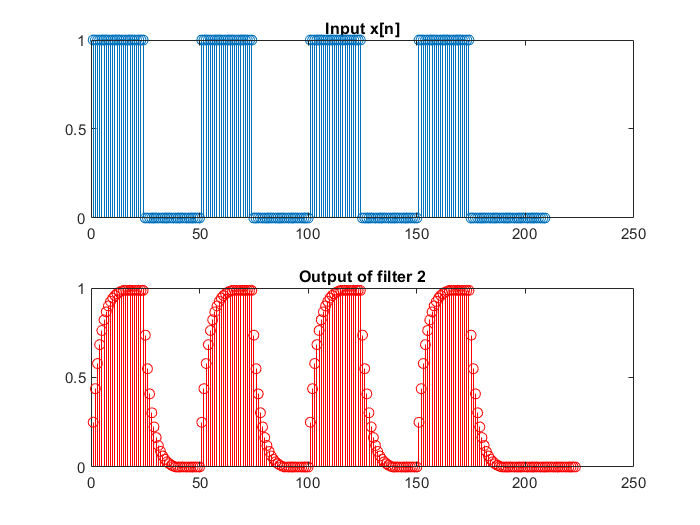

% Defining second filter h2[n]

n=[0:14];
for k=0:14
    h2_n(k+1)=0.25*(0.75)^k;
end
figure(3);
subplot(2,1,1);
stem(x_n);
title('Input x[n]');
y2_n=myconv(x_n,h2_n);
subplot(2,1,2);
stem(y2_n,'r');
title('Output of filter 2');

## 2-1-d

### The given transfer function can be rewritten as 

### H(z)=-0.2z^-5 + z^-4 + -4z^-3 + 12z^-2 - 24z^-1 

### so:

### h[n]= -0.2 x[n-5] + x[n-4]  -4x[n-3] + 12x[n-2] -24x[n-1]

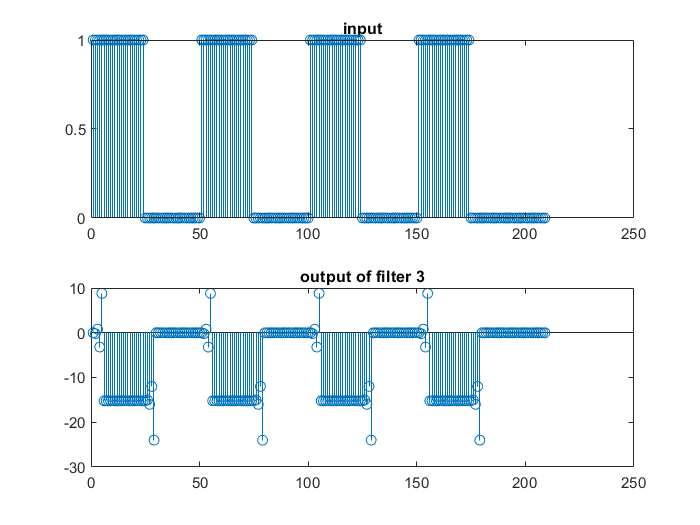


% Defining h3[n]
%----------------------------------------------
x3_n_shifts={};


for i=1:5
    x3_n_shifts{i}=[zeros(1,i) x_n(1:(209-i))];
    
end

k=[-0.2 1 -4 12 -24];
total=zeros(1,length(x3_n_shifts{i}));
for i=1:5
    total= total + k(i) .* x3_n_shifts{i};
end

y3_n=total;

figure(4);
subplot(2,1,1);
stem(x_n);
title('input');
subplot(2,1,2);
stem(y3_n);
title('output of filter 3')

# 2-2

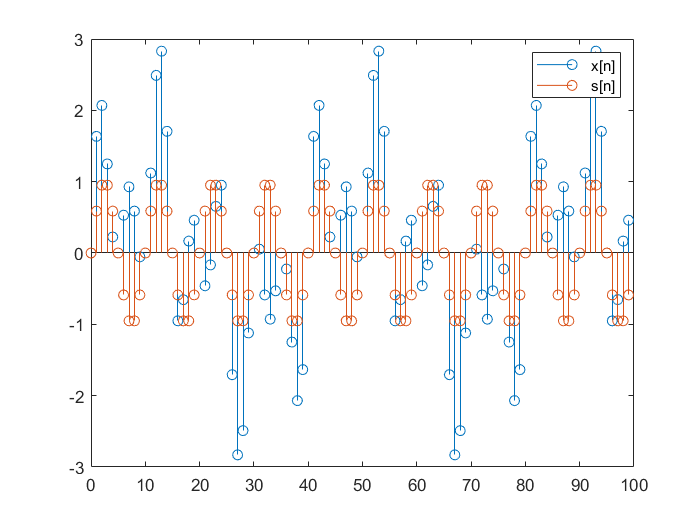


M  = 100;
n  = 0 : M - 1;
w_one = 0.05 * pi;
w_two = 0.20 * pi;
w_three = 0.35 * pi;
wa=0.15*pi;
wb=0.25*pi;

sn=sin(w_two * n);
vn=sin(w_one * n) + sin(w_three * n);
xn=sn+vn;

wn  = 0.54 - 0.46 * sin(2 * pi * n / M);
hn  = wn .* ( wb * sinc(wb * (n - M/2)/pi)/pi - wa * sinc(wa * (n - M/2)/pi)/pi );



figure;
stem(n , xn);
hold on;
stem(n , sn);
legend('x[n]','s[n]');
hold off;

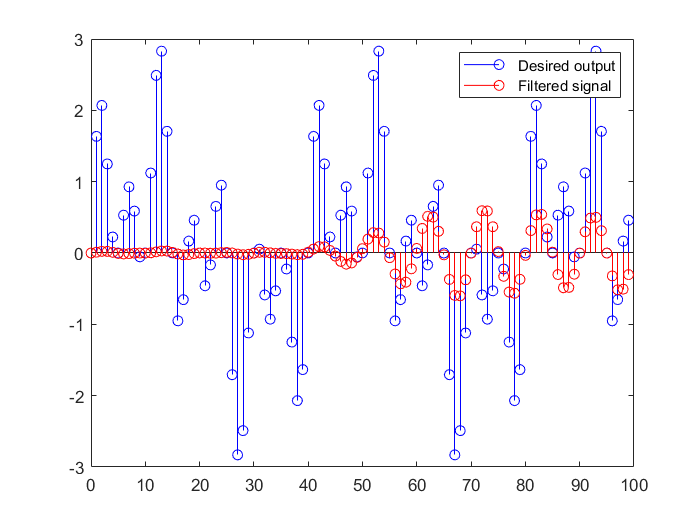



% Applying the filter
y = filter(hn,1,xn);
figure;
stem(n,xn,'b');
hold on;
stem(n, y, 'r');
legend('Desired output','Filtered signal');




% Designing filter by using FDAT tool in MATLAB

y_2 = filter(FDA(:),1,xn);

Reference to a cleared variable FDA.


y = filter(hn,1,xn);
figure;
stem(n,xn,'b');
hold on;
stem(n, y_2, 'r');
legend('Desired output','Filtered signal');



function y = myconv(x,h)
size_x = length(x);
size_h = length(h);
h_pad = [h zeros(1, size_x - 1)];
c = [h(1) zeros(1, size_x - 1)];
H = toeplitz(c, h_pad); 
y=x*H;
end